# IOPID max period estimating template

This is a template for estimating largest sampling period of IOPID controller. Change this file and save to a new script.

tic
clc;clear;
array_size=512;
controller_type='FOPD';
h=linspace(0.1,10,array_size); %
omega=zeros(length(h),1);
f_h=zeros(length(h),1);
parpool(16);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 16 workers.


parfor n=1:array_size
    fprintf('\n====Adding time stamps:%s====\n',...
        datestr(now,'yyyy/mm/dd-HH:MM:SS.FFF'));
    fprintf('Step: %d/%d\n',n,array_size);
    fprintf('Calling sub-layer function.');
%     [ omega(n),f_h(n) ]=cal_f_h(h(n));
    [ omega(n),f_h(n) ]=cal_f_h_selector(h(n),controller_type);
    fprintf('Displaying results:');
    disp(['h=' num2str(h(n))]);
    disp(['f_h=' num2str(f_h(n))]);
end


====Adding time stamps:2018/10/25-14:00:27.837====

====Adding time stamps:2018/10/25-14:00:27.853====

====Adding time stamps:2018/10/25-14:00:27.870====

====Adding time stamps:2018/10/25-14:00:27.843====

====Adding time stamps:2018/10/25-14:00:27.869====

====Adding time stamps:2018/10/25-14:00:27.857====

====Adding time stamps:2018/10/25-14:00:27.871====

====Adding time stamps:2018/10/25-14:00:27.887====

====Adding time stamps:2018/10/25-14:00:27.834====

====Adding time stamps:2018/10/25-14:00:27.855====

====Adding time stamps:2018/10/25-14:00:27.880====

====Adding time stamps:2018/10/25-14:00:27.886====

====Adding time stamps:2018/10/25-14:00:27.858====

====Adding time stamps:2018/10/25-14:00:27.861====

====Adding time stamps:2018/10/25-14:00:27.841====

====Adding time stamps:2018/10/25-14:00:27.873====
Step: 2/512
Step: 4/512
Step: 6/512
Step: 8/512
Step: 10/512
Step: 13/512
Step: 17/512
Step: 22/512
Step: 28/512
Step: 35/512
Step: 44/512
Step: 55/512
Step: 69/512
Ste

Saving data

datafilename=['f_h_' controller_type '_01_100_' num2str(array_size) '.mat'];
save(datafilename);%f_h_iopid_01_100_512.mat
% %datafilename; % filename not correct.
fprintf('Saved data file: %s', datafilename);

Saved data file: f_h_FOPD_01_100_512.mat

We can either load the saved data or run the code above.

load 

%% Plotting section
plot(h,f_h,'-o');

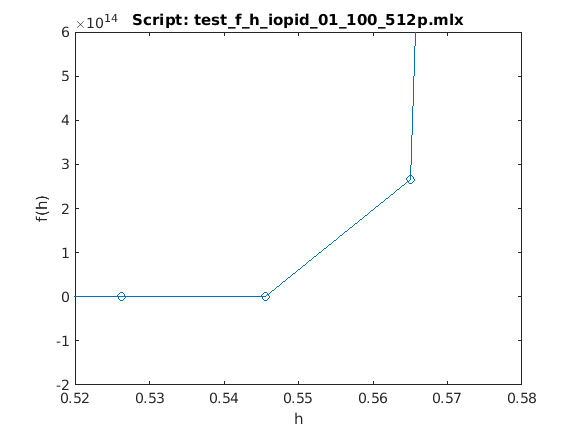

xlabel('h');
ylabel('f(h)');
title(['Script: ' ...
    'test\_f\_h\_iopid\_01\_100\_' num2str(array_size) 'p.mlx']);
%axis([0 1.5 0 10]);
% Change the file names.
saveas(gcf,['f_h_iopid_01_100_' num2str(array_size) '.fig']);
saveas(gcf,['f_h_iopid_01_100_' num2str(array_size) '.png']);
axis([0 10 -5 5]);
saveas(gcf,['f_h_iopid_01_100_' num2str(array_size) 'cross.png']);
saveas(gcf,['f_h_iopid_01_100_' num2str(array_size) 'cross.fig']);
axis([0.52 0.58 -2e14 6e14]);
saveas(gcf,['f_h_iopid_01_100_' num2str(array_size) '_0546.png']);

saveas(gcf,['f_h_iopid_01_100_' num2str(array_size) '_0546.fig']);
disp('Figure saved.')

Figure saved.


toc

Elapsed time is 269.044910 seconds.
